# **Creating a Flight Tracking Dashboard, Part 2: Developing an Aircraft Chart**

MATLAB [Graphics and App Building Blog](https://blogs.mathworks.com/graphics-and-apps/)

*Guest Writer: *[*Ken Deeley*](https://www.mathworks.com/matlabcentral/profile/authors/2987674)

*Joining us again is Ken Deeley, an Application Engineer based in Cambridge, UK. Discover more about Ken on our *[*contributors bio page.*](https://blogs.mathworks.com/graphics-and-apps/contributors/)

**Overview**

In the [first blog post](https://blogs.mathworks.com/graphics-and-apps/2024/02/08/creating-a-flight-tracking-dashboard-part-1-visualizing-an-aircraft/) of this series, we saw how to visualize a model of the aircraft together with its current attitude. In this post, we'll see how to encapsulate the 3D graphics and helper functions used to visualize the aircraft in a custom chart. 

Throughout this post, we'll use the term *chart* to refer to a MATLAB class that provides a convenient visualization API for end users. Charts are also more suitable for modular application development, since they can be dynamically updated after creation, and reused between multiple applications. For more information about charts, see the [technical article](https://www.mathworks.com/company/newsletters/articles/creating-specialized-charts-with-matlab-object-oriented-programming.html) [1].

By the end of this post, we'll have an aircraft chart equipped with the `roll`, `pitch`, and `yaw` functions for setting the attitude of the aircraft.

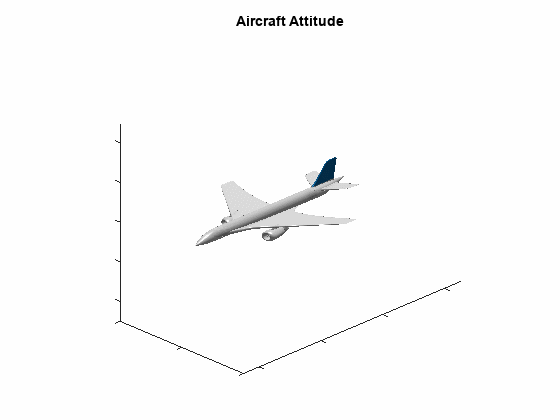

## Create a new chart class.

Since R2019b, MATLAB provides a [framework for developing custom charts](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chartcontainer.chartcontainer-class.html). We'll start by creating a new chart class within this framework, named `AircraftChart`.

In this example, the chart will only contain graphics objects. If you need your chart to contain control objects, such as buttons or check boxes, or if you need to share your chart as a reusable component in App Designer, you should use the [`ComponentContainer`](https://www.mathworks.com/help/matlab/ref/matlab.ui.componentcontainer.componentcontainer-class.html) framework (introduced in R2020b). We’ll see some examples of components in part 3 of this blog series.

## Define the `setup` and `update` methods.

If we try to create an `AircraftChart` object from our class, we'll get the following error.

This is because charts derived from `ChartContainer` must implement the following two methods:

- `setup` - responsible for initializing the chart's graphics as part of the construction process.

- `update` - responsible for refreshing the chart's graphics when the chart's data or properties are changed by an end user.

Let's add these methods to our `AircraftChart`. Note that we need to make these methods *protected* (i.e., accessible within the current class and any subclasses) for consistency with `ChartContainer`.

We can now create a chart object:

This is not very useful though - we don't yet have any data or graphics.

## Add data to the chart.

As we saw in the [first blog post](https://blogs.mathworks.com/graphics-and-apps/2024/02/08/creating-a-flight-tracking-dashboard-part-1-visualizing-an-aircraft/), the data required for the visualization can be represented conveniently as a single [`triangulation`](https://www.mathworks.com/help/matlab/ref/triangulation.html) object. Let's add this as a property in the `AircraftChart` class. As the default value, we'll use the triangulation obtained from the `avion31` STL file we used previously.

The end user of the chart can easily change the aircraft STL file by setting the `Triangulation` property.

The `update` method is called automatically when the end user sets any public property of the chart. This is the mechanism we'll use to ensure the chart updates dynamically in response to changes made by the end user. Before we do this, we need to add graphics objects to the chart.

## Add graphics objects to the chart.

The `ChartContainer` framework provides a [tiled layout](https://www.mathworks.com/help/matlab/ref/tiledlayout.html) in which to add the chart's graphics objects. We can access this tiled layout using the [`getLayout`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chartcontainer.chartcontainer.getlayout.html) method. The tiled layout provides the flexibility to add multiple axes, or axes with different types such as [`geoaxes`](https://www.mathworks.com/help/matlab/ref/geoaxes.html) or [`polaraxes`](https://www.mathworks.com/help/matlab/ref/polaraxes.html).

 In this example, we need to initialize the following graphics objects:

- An [`axes`](https://www.mathworks.com/help/matlab/ref/axes.html) object, that we'll parent to the tiled layout.

- A transform object created using [`hgtransform`](https://www.mathworks.com/help/matlab/ref/hgtransform.html), that we'll parent to the axes. This is used to enable easy rotation of the aircraft around the three coordinate axes.

- A [`patch`](https://www.mathworks.com/help/matlab/ref/patch.html) object, that we'll parent to the transform object. Recall that we used the [`trisurf`](https://www.mathworks.com/help/matlab/ref/trisurf.html) function to create the patch.

First, we'll add the graphics objects as chart properties.

There's no reason for an end user to retrieve or modify these objects directly, so we declare the attribute `Access = private` for these properties. 

We also add [property validation](https://www.mathworks.com/help/matlab/matlab_oop/validate-property-values.html) to ensure that these properties are used correctly within the class. Each of these properties should either be empty (when the class is first loaded) or a scalar value (when the `setup` method is called). Using the size validation `(:, 1)` combined with the validator [`mustBeScalarOrEmpty`](https://www.mathworks.com/help/matlab/ref/mustbescalarorempty.html) ensures that these properties either have size 0-by-1 or 1-by-1.

The type validation (e.g., `matlab.graphics.axis.Axes`) ensures that code within the class assigns values of the correct data type, e.g., to avoid confusion between the different types of axes. Conveniently, adding this type validation also enables tab-completion on properties of the graphics objects when these properties are referenced in methods. 

Don't worry if these class names seem long - it's easy to discover the appropriate type to use by creating a graphics object at the command line and calling the [`class`](https://www.mathworks.com/help/matlab/ref/class.html) function.

Next, we'll create and assign the graphics objects in the chart's `setup` method. This is called automatically whenever a chart object is created. Here, we place the code we used in the [first blog post](https://blogs.mathworks.com/graphics-and-apps/2024/02/08/creating-a-flight-tracking-dashboard-part-1-visualizing-an-aircraft/) for creating the axes, transform, and patch objects.

Note that we do not include creation of the figure within the chart class. This is because a chart does not own or maintain a figure. Rather, it's best to think of a chart as a graphics object that may be placed in a figure, or any other appropriate container, e.g., a tab within a tab group, a panel, another tiled layout, or a grid layout. This is an important concept when using the chart in a modular application.

## Customize the chart's constructor.

We'd like our chart to have a convenient, user-friendly API for end users to work with. To enable autocompletion on the input arguments accepted by the chart, we'll modify the default constructor of `AircraftChart`. 

Chart constructors should accept name-value pair arguments, so we maintain this behavior using an [arguments block](https://www.mathworks.com/help/matlab/matlab_prog/function-argument-validation-1.html), [validating the name-value pairs](https://www.mathworks.com/help/matlab/matlab_prog/validate-name-value-arguments.html) from properties of the `AircraftChart` class.

We also set any name-value pairs on the chart that the end user has passed in to the constructor.

## Update the chart's graphics.

The `AircraftChart` has one public property (`Triangulation`). When the end user sets this property, we expect the chart to update dynamically. This is the purpose of the `update` method. In our example, to avoid deleting and recreating the patch object, which could impair performance, we update the properties of the existing patch. This code uses the [face-vertex representation](https://www.mathworks.com/help/matlab/creating_plots/how-patch-data-relates-to-a-colormap.html) of the patch object.

In general, we can provide end users with a rich API comprising many properties for customizing the style and appearance of the chart. The `update` method handles changes made by the end user to these properties by refreshing the chart's private graphics properties.

## Equip the chart with rotation methods.

Next, we'll transfer the `roll`, `pitch`, and `yaw` functions we discussed in the [first blog post](https://blogs.mathworks.com/graphics-and-apps/2024/02/08/creating-a-flight-tracking-dashboard-part-1-visualizing-an-aircraft/) to the `AircraftChart`. These will become public methods of the chart, available for end users to call.

On the other hand, the `rotate` helper function will become a private chart method, since an end user should not call this method directly.

It's good practice to include a method for restoring the original state of the chart. We'll do this by adding a `reset` method that sets the transformation matrix back to its original value of $I_4$, the 4-by-4 identify matrix.

## Test the chart.

We're now ready to test the chart! Let's try out a 360-degree roll. Note that we’ve added a [`pause`](https://www.mathworks.com/help/matlab/ref/pause.html) command to slow down the animation speed and ensure that each iteration of the loop is captured as a single frame in the resulting animation.

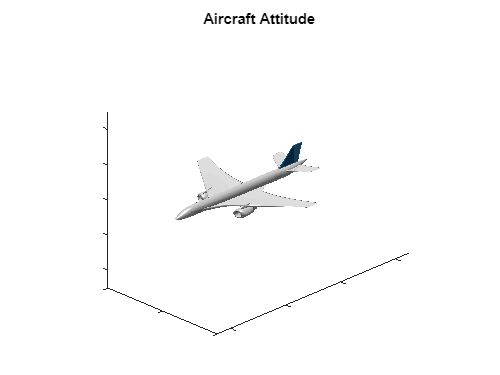

f = figure;
AC = AircraftChart( "Parent", f );

for k = 1 : 72
    AC.roll( 5 )    
    pause( 0.05 )
end

## Further charts.

Taking a similar approach, we could wrap up the graphics required for the map plot used on the dashboard into a custom chart named `LocationChart`. This chart encapsulates the following graphics objects:

- A geographics axes (see [`geoaxes`](https://www.mathworks.com/help/matlab/ref/geoaxes.html))

- Line objects used for the flight path of the aircraft and the current position marker (see [`geoplot`](https://www.mathworks.com/help/matlab/ref/geoplot.html)).

In the third part of this series, we’ll provide all the code for the components that make up the dashboard.

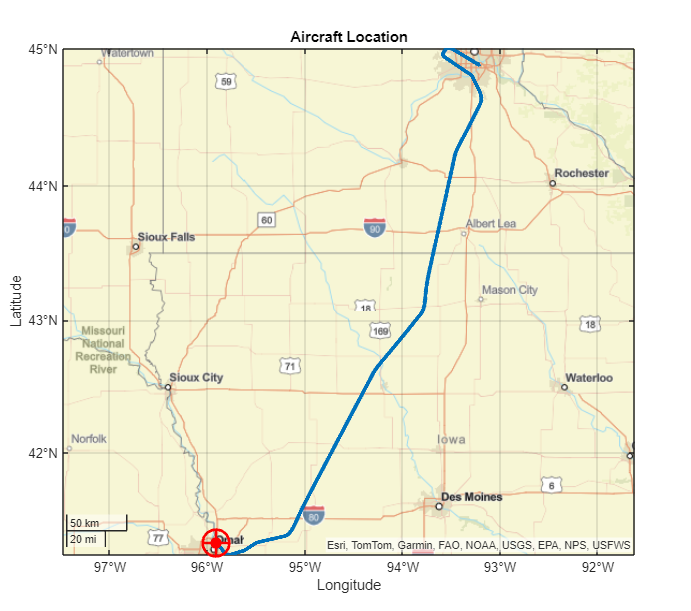

## Summary

We've seen how to take our initial visualization code for the aircraft and encapsulate it into a reusable chart. The chart can be used by colleagues as a standalone visualization within a script or function, or integrated into a larger application. We've also introduced some best programming practices for developing a chart class in MATLAB. 

In the next post, we'll see how to build up the dashboard by writing further modular components and integrating them into a MATLAB app.

## References

[1] [*Creating Specialized Charts with MATLAB Object-Oriented Programming*](https://www.mathworks.com/company/newsletters/articles/creating-specialized-charts-with-matlab-object-oriented-programming.html), Ken Deeley and David Sampson (2018).